# 1.1.10 Введение в MATLAB

## Практическое занятие

## Векторные и матричные операции

# Задача 1. Длина вектора

Длина вектора $\overline{a}$ равна квадратному корню из суммы квадратов его координат:


$$\overline{a} =\sqrt{\sum_{k=1}^n a_k^2 }$$


где k - номер элемента вектора, n - общее число элементов в векторе.

Вычислить длину вектора $\overline{a} =\left(2;3;4\right)$.

a = [2 3 4];
sqrt(sum(a.*a))

ans = 5.3852

# Задача 2. Направляющие косинусы вектора

Пусть дан вектор $\overline{a}$. Обозначим углы наклона этого вектора к осям *Ox*, *Oy* и *Oz* соответственно через $\alpha ,\beta ,\gamma \ldotp$ Три числа $\mathrm{cos}\;\alpha ,\mathrm{cos}\beta$ и $\cos \;\gamma$ являются направляющими косинусами вектора $\overline{a}$. Направляющие косинусы вычисляются по формулам 

$\mathrm{cos}\;\alpha =\frac{a_1 }{\sqrt{a_1^2 +a_2^2 +a_3^2 }}$, $\cos \;\beta =\frac{a_2 }{\sqrt{a_1^2 +a_2^2 +a_3^2 }}$, $\cos \;\gamma =\frac{a_3 }{\sqrt{a_1^2 +a_2^2 +a_3^2 }}$ .

Вычислитe углы наклона ветора $\overline{a} =\left(-1;2;5\right)$к осям координат.

a = [-1,2,5];
acos(a./sqrt(sum(a.*a)))*180/pi

ans =   100.5197   68.5833   24.0948


Убедитесь, что направляющие косинусы удовлетворяют следующему соотношению:


$${\mathrm{cos}}^2 \alpha +{\mathrm{cos}}^2 \beta +{\mathrm{cos}}^2 \gamma =1\ldotp$$


sum(cos(ans./180*pi).^2)

ans = 1

# Задача 3. Скалярное произведение векторов

Скалярным произведением двух векторов называется число,  равное произведения длин этих векторов на косинус угла между ними:

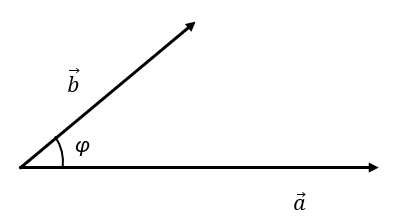

$\overline{a} \cdot \overline{b} =\left|\overline{a} \right|\cdot \left|\overline{b} \right|\cdot \cos \;\varphi$.

Физический смысл скалярного произведения: работа постоянной силы при прямолинейном перемещении точки ее приложения равна скалярному произведению вектора силы на вектор перемещения.

$A=\overline{F} \cdot \overline{S} =\left|\overline{F} \right|\cdot \left|\overline{S} \right|\cdot \cos \;\varphi$.

Найдите работу силы $\overline{F} =\left(2;2\right)$ на перемещение $\overline{S} =\left(5;2\right)$.

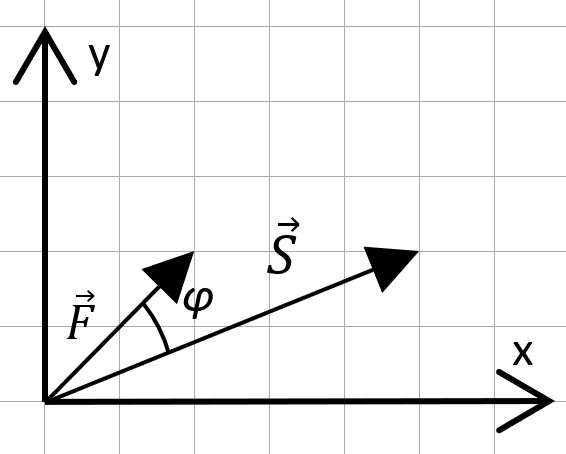

F = [2 2];
S = [5 2];
phi_F = atan2d(F(2),F(1))

phi_F = 45

phi_S = atan2d(S(2),S(1))

phi_S = 21.8014

phi = phi_F - phi_S

phi = 23.1986

A = sqrt(sum(F.*F))*sqrt(sum(S.*S))*cosd(phi)

A = 14.0000

Скалярное произведение двух векторов, заданных в координатной форме, можно вычислить проще:


$$\overline{a} \cdot \overline{b} =a_1 b_1 +a_2 b_2 +{\ldotp \ldotp \ldotp \;+\;a}_n b_n =\sum_{k=1}^n a_k b_k$$


Проверьте с помощью этой формулы, что работа A была вычислена правильно.

[sum(F.*S), dot(F,S)]

ans =     14    14


# Задача 4. Векторное произведение

Вычислить векторное произведение векторов $\overline{a} =\left(1;2;3\right)$и $\overline{b} =\left(3;2;1\right)$

a = [1 2 3];
b = [3 2 1];
c = cross(a,b)

c =     -4     8    -4


# Задача 5. Норма вектора

Первая или кубическая норма - сумма абсолютных значений вектора:


$${\left\|\overline{a} \right\|}_1 =\sum_{i=1}^n \left|a_i \right|$$


Евклидова или сферическая норма:


$${\left\|\bar{a} \right\|}_2 =\sqrt{\sum_{i=1}^n a_i^2 }$$


Бесконечная или октаэдрическая норма:


$${\left\|\bar{a} \right\|}_{\infty } =\underset{1\le i\le n}{\mathrm{max}} \left|a_i \right|$$


Вычислить первую, евклидову и бесконечную нормы вектора $\overline{a} =\left(2;4;6;8\right)\ldotp$

a = [2 4 6 8];
n1 = norm(a,1)

n1 = 20

n2 = norm(a,2)

n2 = 10.9545

nInf = norm(a,inf)

nInf = 8

Величину $\left\|\overline{x} -\overline{y} \right\|$(вторая или евклидова норма) называют растоянием между векторами $\bar{x}$ и $\bar{y}$. Это является обобщением обычного геометрического расстояния между точками. Вычислите наикратчайшее расстояние между точками A(1;3;4) и B(1;-1;2).

A = [1,3,4];
B = [1,-1,-2];
S = norm(A-B)

S = 7.2111

Для определения расстояния между векторами можно использовать и первую норму, которая вычисляет "манхэттенское" расстояние, т.е. число кварталов, которое необходимо пройти, чтобы попасть из пункта A в пункт B. Вычислите "манхэттенское" расстояние между точками A(1;3;4) и B(1;-1;2).

A = [1,3,4];
B = [1,-1,-2];
S = norm(A-B,1)

S = 10

# Задача 6. Создание матриц

Создайте матрицу A, найдите ее определитель:


$$A=\;\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
1 & 2 & 3\\
1 & 2 & 3
\end{array}\right\rbrack$$


A = [1 2 3; 1 2 3; 1 2 3]

A =      1     2     3
     1     2     3
     1     2     3


det(A)

ans = 0

Измените матрицу A, так, чтобы она приобрела следующий вид:


$$A=\;\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
1 & 4 & 4\\
5 & 5 & 3
\end{array}\right\rbrack$$


Проверьте, что ее определитель не равен 0, и найдите обратную матрицу.

A(2,[2,3]) = 4;
A(3,1:2) = 5

A =      1     2     3
     1     4     4
     5     5     3


det(A)

ans = -19

inv(A)

ans =     0.4211   -0.4737    0.2105
   -0.8947    0.6316    0.0526
    0.7895   -0.2632   -0.1053


Создайте матрицу B размера 3х3, которая содержит равномерно распределенные случайные числа в диапазоне от (-0.5, 0.5)

B = rand(3)-0.5

B =    -0.2381   -0.3634    0.1538
   -0.1646    0.2212   -0.0058
    0.1797   -0.3932    0.2791


Сложите матрицы A и B, запишите результат в переменную C

C = A+B

C =     0.7619    1.6366    3.1538
    0.8354    4.2212    3.9942
    5.1797    4.6068    3.2791


Проверьте равенство матриц A и B, а также являются ли они эквивалентными (ранги матриц равны):

$A=\;\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack ;$$\;\;\;\;B=\;\left\lbrack \begin{array}{ccc}
9 & 8 & 7\\
4 & 5 & 6\\
1 & 2 & 3
\end{array}\right\rbrack$.

% Задание матриц
A = reshape(1:9,3,[])'

A =      1     4     7
     2     5     8
     3     6     9


B = flip(A,1);
B(1,:) = flip(B(1,:),2)

B =      9     6     3
     2     5     8
     1     4     7


isequal(A,B)

ans = logical
   0


isequal(rank(A), rank(B))

ans = logical
   1


# Задача 7. Специальные матрицы

Создайте диагональную матрицу D:


$$D=\;\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 3
\end{array}\right\rbrack$$


a = 1:3;
D = diag(a)

D =      1     0     0
     0     2     0
     0     0     3


Создайте матрицу A размера 4х4, в которой на главной диагонали находятся числа 22

A = eye(4)*22

A =     22     0     0     0
     0    22     0     0
     0     0    22     0
     0     0     0    22


Выделить из ранее созданной матрицы B верхнюю и нижнюю треугольные матрицы:

B

B =      9     8     7
     4     5     6
     1     2     3


L = tril(B)

L =      9     0     0
     4     5     0
     1     2     3


U = triu(B)

U =      9     8     7
     0     5     6
     0     0     3


Создайте магический квадрат размером 4х4. Вычислите сумму значений элементов по столбцам, строкам, главной диагонали:

M = magic(4)

M =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


col = sum(M,1)

col =     34    34    34    34


row = sum(M,2)

row =     34
    34
    34
    34


diagonal = trace(M)

diagonal = 34

# Задание 8. Перемножение матриц

Перемножьте матрицы A и B поэлементно:

$A=\;\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack ;$$\;\;\;\;B=\;\left\lbrack \begin{array}{ccc}
9 & 8 & 7\\
4 & 5 & 6\\
1 & 2 & 3
\end{array}\right\rbrack$.

A = reshape(1:9,3,[])';
B = [9 8 7; 4 5 6; 1 2 3];
A.*B

ans =      9    16    21
    16    25    36
     7    16    27


Перемножьте матрицы A и B по правилам линейной алгебры:

$A=\left\lbrack \begin{array}{cc}
2 & 1\\
-3 & 0\\
4 & -1
\end{array}\right\rbrack ;$$\;\;\;\;B=\left\lbrack \begin{array}{ccc}
5 & -1 & 6\\
-3 & 0 & 7
\end{array}\right\rbrack$.

A = [2 1; -3 0; 4 -1]

A =      2     1
    -3     0
     4    -1


B = [5 -1 6; -3 0 7]

B =      5    -1     6
    -3     0     7


C = A*B

C =      7    -2    19
   -15     3   -18
    23    -4    17
